# Probability, Classification, and User Experience

Katie Foster

April 2020

You’ve created a classifier with 98% accuracy that can determine whether someone is clenching their jaw or not at any given time point. You want to use this to create a secret messaging service to covertly get a friend’s attention when something important is happening. 

% 1. If a judgement (clenching or not) is made every 30 seconds, what’s the probability 
% that your device will work perfectly (no errors) if someone uses it for 5 minutes?
0.98^((5*60)/30)

ans = 0.8171

% 2. How does this probability change if your device starts making a judgment every 2 
% seconds instead?
0.98^((5*60)/2)

ans = 0.0483

% 3. How does this probability change if someone uses the device for 20 minutes at a 
% judgment every 30 seconds? 
0.98^((20*60)/30)

ans = 0.4457

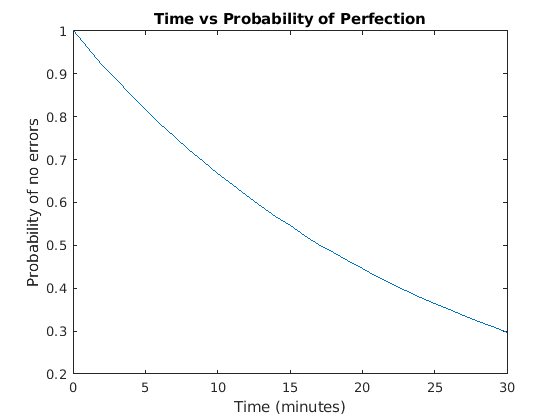

% 4. Plot probability of perfection (experience of having no errors during use time) 
% as a function of time.
x = 0:30;
y = 0.98.^((x*60)/30);
plot(x, y);
xlabel("Time (minutes)"); ylabel("Probability of no errors");
title("Time vs Probability of Perfection");

% 5. How does this probability change for (20 minutes) if you accuracy goes up to 99.9%
0.999^((20*60)/30)

ans = 0.9608

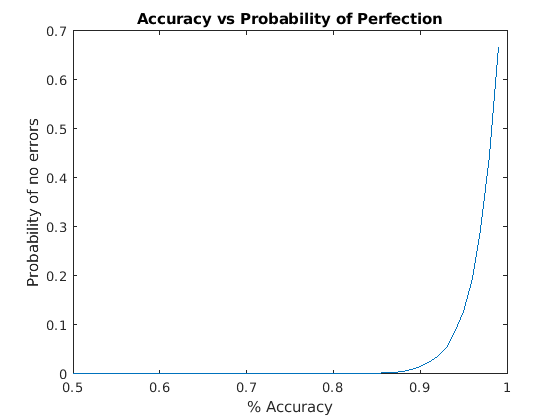

% 6. Plot the probability of a perfect 20 minute use session as a function of accuracy 
% (may want to look at a range between 0.5 and 0.999.
x = 0.5:0.01:0.999;
y = x.^((20*60)/30);
plot(x, y);
xlabel("% Accuracy"); ylabel("Probability of no errors");
title("Accuracy vs Probability of Perfection");

7. Frame a similar problem/question for yourself (this could relate to the application that you thought about last week or the classification accuracies that you were able to achieve) and answer it. 

I decided to think about using such a device to communicate through morse code. This might be interesting as a way to communicate secretly with a friend, or it could have an application of helping someone who does not have full control over their body to communicate. 

I am going to make some assumptions, and throw some numbers here without a very good base for them. 

Average number of symbols (dots or dashes) in a morse code letter or number: 4 (I did look at a chart, this seems to be the median)

Accuracy (ability to tell the difference between a dot, a dash, and a rest): 0.96

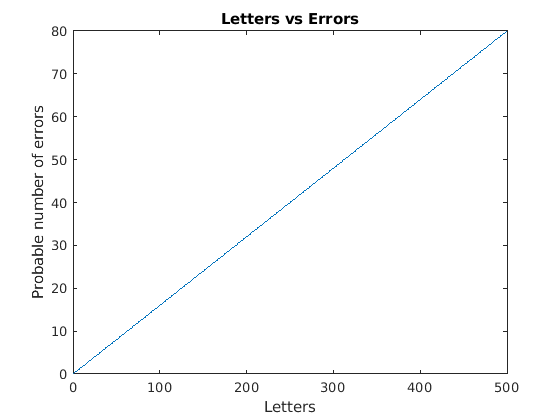

x = 0:500;
y = 0.04*4*x;
plot(x, y);
xlabel("Letters"); ylabel("Probable number of errors");
title("Letters vs Errors");

% yeah, I knew it was going to be linear. Not a very interesting graph. 
% this means 1 out of every 6 letters are incorrect

I was wondering what a 1/6 incorrect letter rate would look like, so I made a python program to randomly replace each letter with a 1/6 chance, with another random letter. The results were pretty unintelligable:

**I put in:**

"Help, I'm stuck in a Python factory!"

"I love the class Neurotechnology, Brains, and Machines"

"If you are reading this, it is probably the future and I am older"

**And what came out was: **

Help, I'm njuck in anPython factory!

t lovl thi clais veurozechlplogy, Braies,dand Maczines

zf you are realing tiiz, it cs probazly the future and I ao oldee

**Then I tried it with replacing 1/20 characters, and that was much more understandable:**

Helo, I'm stuck in a Python factory!

I love the clafs Neurotefhnology, Bryinsa and Machines

If you are readino this, it is probably the future and I am older

**However, the program still made a fatal mistake of replacing the word "Help" with "Helo", which the reciever might read as "Hello", and therefore might not feel the urgent need to save their friend from the Python factory. **

**I realized that this technology would need to have a very high accuracy rate to be usable. **